% problem4_2.m
% 问题四（2）：储能容量最优配置与有储能的最优调度
% 依赖 workspace 变量：wind1~wind6, sun1~sun4, classicload, fenshijijia

wind_vectors = {wind1(:), wind2(:), wind3(:), wind4(:), wind5(:), wind6(:)};
wind_names   = {'wind1', 'wind2', 'wind3', 'wind4', 'wind5', 'wind6'};
sun_vectors  = {sun1(:), sun2(:), sun3(:), sun4(:)};
sun_names    = {'sun1', 'sun2', 'sun3', 'sun4'};

classicload  = classicload(:);
fenshijijia  = fenshijijia(:);
n    = numel(wind_vectors{1});
lb_t = 0.1;

% =========================================================================
% 第一步：计算各场景弃电/缺电向量，确定最大弃电场景
% =========================================================================
fprintf('==================== 弃电/缺电向量分析 ====================\n');

==================== 弃电/缺电向量分析 ====================



slack_vectors  = cell(numel(wind_vectors), numel(sun_vectors));
best_max_slack = -Inf;
best_wind_idx  = 1;
best_sun_idx   = 1;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};

        raw_ub = (wind*40 + sun*64 - classicload*6) / (20.75*2);
        ub_val = min(ones(n,1), raw_ub);

        slack = zeros(n,1);
        for i = 1:n
            if ub_val(i) < lb_t
                slack(i) = ub_val(i) - lb_t;   % 缺电：负值
            elseif raw_ub(i) > 1
                slack(i) = raw_ub(i) - 1;       % 弃电：正值
            end
        end

        slack_vectors{wind_idx, sun_idx} = slack;

        fprintf('\n%s + %s 的 slack 向量如下：\n', wind_names{wind_idx}, sun_names{sun_idx});
        slack_table = table((1:n)', slack, 'VariableNames', {'hour', 'slack'});
        disp(slack_table);

        if max(slack) > best_max_slack
            best_max_slack = max(slack);
            best_wind_idx  = wind_idx;
            best_sun_idx   = sun_idx;
        end
    end

最大弃电场景：wind1 + sun1（最大弃电量 = 0.6422）


end

fprintf('最大弃电场景：%s + %s（最大弃电量 = %.4g）\n', ...
        wind_names{best_wind_idx}, sun_names{best_sun_idx}, best_max_slack);

% =========================================================================
% 第二步：由最大弃电场景计算储能容量
% =========================================================================
best_slack = slack_vectors{best_wind_idx, best_sun_idx};

b 向量：max = 3.261，min = 0


b = cumsum(best_slack);
[max_b, max_b_idx] = max(b);

储能容量 E = (3.261 - 0) * 20.75 * 2 = 135.3 MW·h


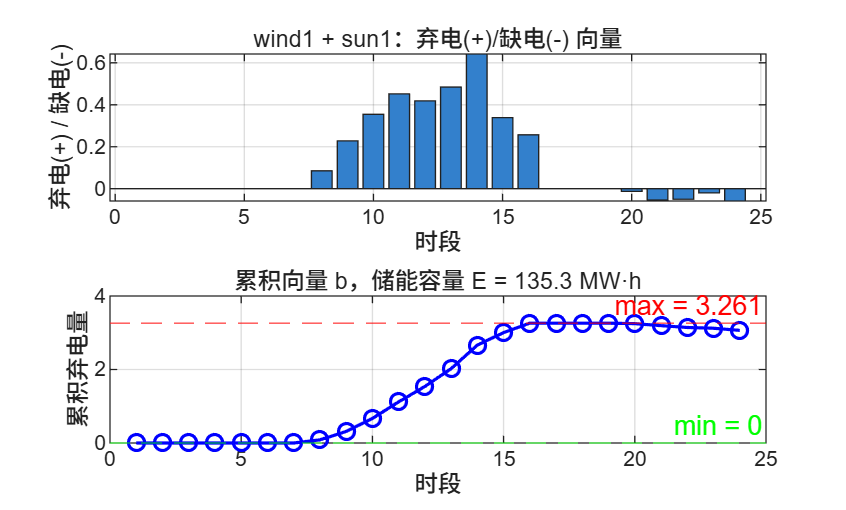

if max_b_idx < numel(b)
    [min_after_max_b, rel_min_idx] = min(b(max_b_idx+1:end));
    min_after_max_b_idx = max_b_idx + rel_min_idx;
else
    min_after_max_b = max_b;
    min_after_max_b_idx = max_b_idx;
    warning('max(b) 位于 b 向量最后一个位置，后面没有可选的最小值，E 按 0 计算。');
end
E = (max_b - min_after_max_b) * 20.75 * 2;

fprintf('b 向量：max = %.4g（位置 %d），max 后面的 min = %.4g（位置 %d）
', ...
        max_b, max_b_idx, min_after_max_b, min_after_max_b_idx);
fprintf('储能容量 E = (%.4g - %.4g) * 20.75 * 2 = %.4g MW·h
', ...

        max_b, min_after_max_b, E);

figure('Name', 'problem4-2：最大弃电场景储能分析', 'Color', 'w');
subplot(2,1,1);
bar(best_slack, 'FaceColor', [0.2 0.5 0.8]);



==================== 有储能最优调度（24 场景）====================


grid on;

储能容量 E = 135.3 MW·h



title(sprintf('%s + %s：弃电(+)/缺电(-) 向量', ...
      wind_names{best_wind_idx}, sun_names{best_sun_idx}), 'Interpreter', 'none');
xlabel('时段'); ylabel('弃电(+) / 缺电(-)');

subplot(2,1,2);
plot(b, 'b-o', 'LineWidth', 1.2); grid on;
yline(max(b), 'r--', sprintf('max = %.4g', max(b)));
yline(min(b), 'g--', sprintf('min = %.4g', min(b)));
title(sprintf('累积向量 b，储能容量 E = %.4g MW·h', E), 'Interpreter', 'none');
xlabel('时段'); ylabel('累积弃电量');

% =========================================================================
% 第三步：有储能的最优调度（24 场景）
% =========================================================================
fprintf('\n\n==================== 有储能最优调度（24 场景）====================\n');
fprintf('储能容量 E = %.4g MW·h\n\n', E);

opts_lp = optimoptions('linprog', 'Display', 'off');
storage_results = struct([]);
res_idx = 0;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    wind_name = wind_names{wind_idx};

    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};
        sun_name = sun_names{sun_idx};

        fprintf('\n==================== 情况 %02d：%s + %s ====================\n', ...
                (wind_idx-1)*numel(sun_vectors)+sun_idx, wind_name, sun_name);

        % 决策变量 x = [t(n); SOC(n); ch(n); dis(n); buy(n); sell(n)]
        % 目标：最大化 sum(t) ↔ 最小化 -sum(t)
        f_lp  = [-ones(n,1); zeros(5*n,1)];
        lb_lp = [lb_t*ones(n,1); zeros(5*n,1)];
        ub_lp = [ones(n,1); E*ones(n,1); Inf(4*n,1)];

        % 等式约束 1：逐时段功率平衡
        % 20.75*2*t[i] + ch[i] - dis[i] - buy[i] + sell[i]
        %   = wind[i]*40 + sun[i]*64 - classicload[i]*6
        Aeq1 = [diag(repmat(20.75*2, n, 1)), zeros(n,n), ...
                eye(n), -eye(n), -eye(n), eye(n)];
        beq1 = wind*40 + sun*64 - classicload*6;

        % 等式约束 2：SOC 动态（初始 SOC[0] = 0）
        % SOC[i] - SOC[i-1] - ch[i] + dis[i] = 0
        SOC_coef = eye(n) - diag(ones(n-1,1), -1);
        Aeq2 = [zeros(n,n), SOC_coef, -eye(n), eye(n), zeros(n,n), zeros(n,n)];
        beq2 = zeros(n,1);

        Aeq = [Aeq1; Aeq2];
        beq = [beq1; beq2];

        [x_sol, ~, exitflag] = linprog(f_lp, [], [], Aeq, beq, lb_lp, ub_lp, opts_lp);

        if exitflag ~= 1
            fprintf('LP 求解失败（exitflag=%d），跳过。\n', exitflag);
            continue;
        end

        t_opt    = x_sol(1:n);
        soc_opt  = x_sol(n+1:2*n);
        ch_opt   = x_sol(2*n+1:3*n);
        dis_opt  = x_sol(3*n+1:4*n);
        buy_opt  = x_sol(4*n+1:5*n);
        sell_opt = x_sol(5*n+1:6*n);

        sum_t = sum(t_opt);
        fprintf('有储能 sum(t) = %.6g\n', sum_t);

        % 能量指标
        nh3load_vec = t_opt * 20.75 * 2;
        load_vec    = classicload*6 + nh3load_vec;
        gen_vec     = wind*40 + sun*64;

        dayload     = sum(load_vec);
        daygenerate = sum(gen_vec);
        daybuy      = sum(buy_opt);
        daysell     = sum(sell_opt);

        xnyzf = (dayload - daysell - daybuy) / daygenerate;
        zydl  = (daygenerate - daysell) / dayload;
        xnysw = daysell / daygenerate;

        % 成本计算（与 objFun 保持一致）
        buycost  = sum(buy_opt .* fenshijijia);
        sellcost = -sum(sell_opt) * 377.9;         % 卖电收益（负成本）
        cost_total = buycost + sellcost ...
                   + 0.75*2*sum_t*2 ...
                   + 1.5*2*1000*0.2*60000/365/30 ...
                   + 10*2*sum_t*100 ...
                   + 10*2*sum_t*150 ...
                   + sum(sun)*64*1000*0.12 ...
                   + sum(wind)*40*1000*0.15;

        J_storage       = cost_total / (sum_t * 3);
        annual_nh3      = sum_t * 3 * 365;          % 全年制氨量（吨）
        cap_utilization = sum_t / n;                % 年平均产能利用率

        fprintf('吨氨成本 J = %.6g\n',    J_storage);
        fprintf('全年制氨总量 = %.6g 吨\n', annual_nh3);
        fprintf('年平均产能利用率 = %.4f\n', cap_utilization);
        fprintf('xnyzf=%.6g，zydl=%.6g，xnysw=%.6g\n', xnyzf, zydl, xnysw);

        res_idx = res_idx + 1;
        storage_results(res_idx).case_idx        = res_idx;
        storage_results(res_idx).wind_idx        = wind_idx;
        storage_results(res_idx).wind_name       = wind_name;
        storage_results(res_idx).sun_idx         = sun_idx;
        storage_results(res_idx).sun_name        = sun_name;
        storage_results(res_idx).t_opt           = t_opt;
        storage_results(res_idx).soc_opt         = soc_opt;
        storage_results(res_idx).ch_opt          = ch_opt;


==================== 情况 01：wind1 + sun1 ====================


有储能 sum(t) = 24


吨氨成本 J = 5430.08


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=0.644709，zydl=0.592816，xnysw=0.177646



==================== 情况 02：wind1 + sun2 ====================


有储能 sum(t) = 24


吨氨成本 J = 6802.67


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=0.970389，zydl=0.469144，xnysw=0.0148055



==================== 情况 03：wind1 + sun3 ====================


有储能 sum(t) = 24


吨氨成本 J = 8163.38


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.319332，xnysw=0



==================== 情况 04：wind1 + sun4 ====================


有储能 sum(t) = 24


吨氨成本 J = 8711.89


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.258161，xnysw=0



==================== 情况 05：wind2 + sun1 ====================


有储能 sum(t) = 24


吨氨成本 J = 5835.93


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=0.727997，zydl=0.538735，xnysw=0.136002



==================== 情况 06：wind2 + sun2 ====================


有储能 sum(t) = 24


吨氨成本 J = 7365.76


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.378855，xnysw=0



==================== 情况 07：wind2 + sun3 ====================


有储能 sum(t) = 24


吨氨成本 J = 8770.4


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.221993，xnysw=0



==================== 情况 08：wind2 + sun4 ====================


有储能 sum(t) = 24


吨氨成本 J = 9318.91


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.160822，xnysw=0



==================== 情况 09：wind3 + sun1 ====================


有储能 sum(t) = 24


吨氨成本 J = 5282.33


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=0.676328，zydl=0.619343，xnysw=0.161836



==================== 情况 10：wind3 + sun2 ====================


有储能 sum(t) = 24


吨氨成本 J = 6664.22


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=0.98573，zydl=0.49072，xnysw=0.00713487



==================== 情况 11：wind3 + sun3 ====================


有储能 sum(t) = 24


吨氨成本 J = 8046.89


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.337384，xnysw=0



==================== 情况 12：wind3 + sun4 ====================


有储能 sum(t) = 24


吨氨成本 J = 8595.4


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.276213，xnysw=0



==================== 情况 13：wind4 + sun1 ====================


有储能 sum(t) = 24


吨氨成本 J = 4935.96


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=0.603829，zydl=0.665472，xnysw=0.198086



==================== 情况 14：wind4 + sun2 ====================


有储能 sum(t) = 24


吨氨成本 J = 6183.23


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=0.968497，zydl=0.575956，xnysw=0.0157516



==================== 情况 15：wind4 + sun3 ====================


有储能 sum(t) = 24


吨氨成本 J = 7535.69


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.42831，xnysw=0



==================== 情况 16：wind4 + sun4 ====================


有储能 sum(t) = 24


吨氨成本 J = 8084.21


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.36714，xnysw=0



==================== 情况 17：wind5 + sun1 ====================


有储能 sum(t) = 24


吨氨成本 J = 5178.19


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=0.612789，zydl=0.625308，xnysw=0.193605



==================== 情况 18：wind5 + sun2 ====================


有储能 sum(t) = 24


吨氨成本 J = 6450.76


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=0.964874，zydl=0.521434，xnysw=0.017563



==================== 情况 19：wind5 + sun3 ====================


有储能 sum(t) = 24


吨氨成本 J = 7797.32


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.373893，xnysw=0



==================== 情况 20：wind5 + sun4 ====================


有储能 sum(t) = 24


吨氨成本 J = 8345.83


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.312722，xnysw=0



==================== 情况 21：wind6 + sun1 ====================


有储能 sum(t) = 24


吨氨成本 J = 5513.1


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=0.74621，zydl=0.59139，xnysw=0.126895



==================== 情况 22：wind6 + sun2 ====================


有储能 sum(t) = 24


吨氨成本 J = 7036.67


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.43266，xnysw=0



==================== 情况 23：wind6 + sun3 ====================


有储能 sum(t) = 24


吨氨成本 J = 8441.31


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.275797，xnysw=0



==================== 情况 24：wind6 + sun4 ====================


有储能 sum(t) = 24


吨氨成本 J = 8989.82


全年制氨总量 = 26280 吨


年平均产能利用率 = 1.0000


xnyzf=1，zydl=0.214626，xnysw=0


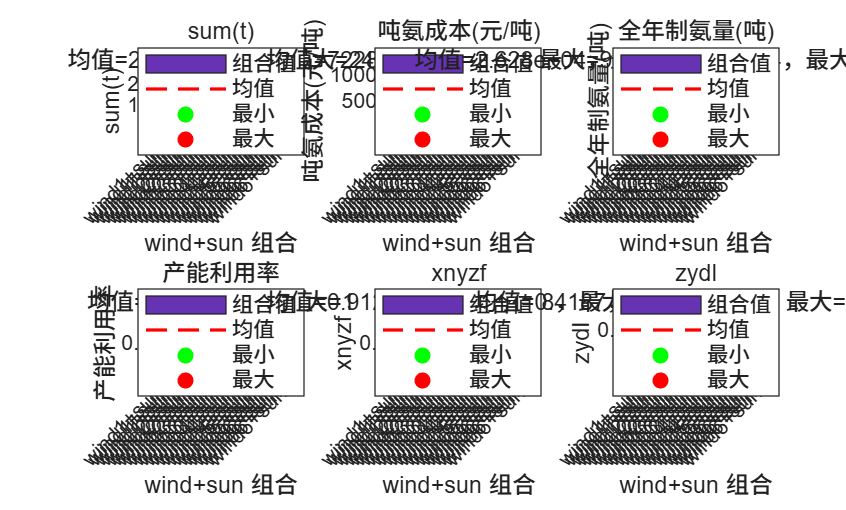

        storage_results(res_idx).dis_opt         = dis_opt;
        storage_results(res_idx).buy             = buy_opt;
        storage_results(res_idx).sell            = sell_opt;
        storage_results(res_idx).sum_t           = sum_t;
        storage_results(res_idx).daybuy          = daybuy;

        storage_results(res_idx).daysell         = daysell;
        storage_results(res_idx).dayload         = dayload;
        storage_results(res_idx).daygenerate     = daygenerate;
        storage_results(res_idx).xnyzf           = xnyzf;
        storage_results(res_idx).zydl            = zydl;
        storage_results(res_idx).xnysw           = xnysw;
        storage_results(res_idx).J               = J_storage;
        storage_results(res_idx).annual_nh3      = annual_nh3;
        storage_results(res_idx).cap_utilization = cap_utilization;
    end
end

% =========================================================================
% 第四步：绘图
% =========================================================================
plotStorageResults(storage_results, E);

% =========================================================================
% 局部函数
% =========================================================================
function plotStorageResults(storage_results, E)
    if isempty(storage_results)
        warning('没有可绘制的结果。');
        return;
    end

    sort_keys = [[storage_results.wind_idx]', [storage_results.sun_idx]'];
    [~, order] = sortrows(sort_keys, [1 2]);
    storage_results = storage_results(order);

    combo_labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), ...
                            storage_results, 'UniformOutput', false);

    metric_fields = {'sum_t', 'J', 'annual_nh3', 'cap_utilization', 'xnyzf', 'zydl'};
    metric_names  = {'sum(t)', '吨氨成本(元/吨)', '全年制氨量(吨)', ...
                     '产能利用率', 'xnyzf', 'zydl'};

    figure('Name', sprintf('problem4-2：有储能(E=%.4gMWh)各场景指标', E), 'Color', 'w');

    for mi = 1:numel(metric_fields)
        values = arrayfun(@(r) r.(metric_fields{mi}), storage_results);
        valid  = values(~isnan(values));

        subplot(2, 3, mi);
        bar(values, 'FaceColor', [0.4 0.2 0.7]);
        grid on; hold on;

        mean_v = mean(valid);
        plot(xlim, [mean_v mean_v], 'r--', 'LineWidth', 1.2);

        [~, min_idx] = min(values);
        [~, max_idx] = max(values);
        scatter(min_idx, min(valid), 45, 'g', 'filled');
        scatter(max_idx, max(valid), 45, 'r', 'filled');

        title({metric_names{mi}, sprintf('均值=%.4g，最小=%.4g，最大=%.4g', ...
               mean_v, min(valid), max(valid))}, 'Interpreter', 'none');
        xlabel('wind+sun 组合');
        ylabel(metric_names{mi}, 'Interpreter', 'none');
        set(gca, 'XTick', 1:numel(combo_labels), ...
                 'XTickLabel', combo_labels, 'XTickLabelRotation', 45);
        xlim([0.5, numel(combo_labels)+0.5]);
        legend({'组合值','均值','最小','最大'}, 'Location','best','FontSize',8);
        hold off;
    end
end